# Brown Index

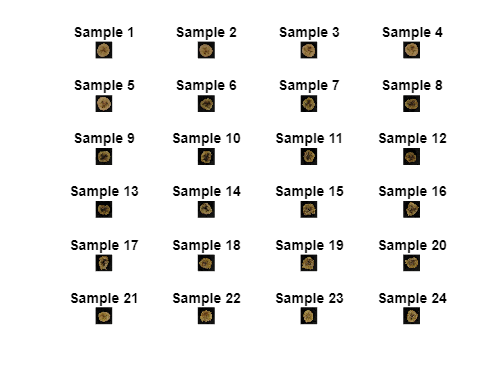

% Define the path to the images
fig_path = 'C:\Users\yingf\Desktop\My phd\1\Banana\CV\Pretreatment 1\Control\';
cd(fig_path);

% Get all image files in the directory
allfigs = dir('*.JPG');
img_num = length(allfigs);

% Initialize cell array to store images
img_origin = cell(img_num, 1);

% Load all images into the cell array
for i = 1:img_num
    img_origin{i} = imread(allfigs(i).name);
end

% Create a figure to display the images
figure;
numRows = 6; % Number of rows in subplot grid
numCols = ceil(img_num / numRows); % Number of columns in subplot grid

% Display the images in a subplot grid
for i = 1:img_num
    subplot(numRows, numCols, i);
    imshow(img_origin{i});
    title(['Sample ' num2str(i)]);
end

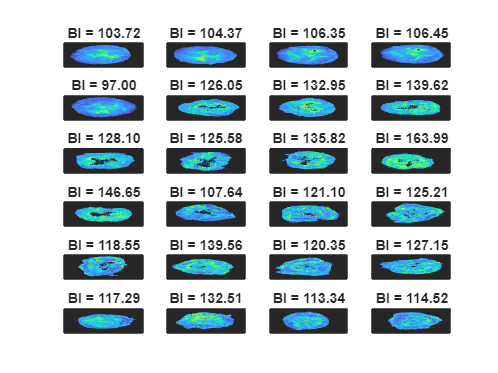


% Create a new figure for displaying the BI heatmaps
figure,
numRows = 6; % Number of rows in subplot grid for BI heatmaps
numCols = 4; % Number of columns in subplot grid for BI heatmaps

% Process each image to calculate the Brown Index (BI)
for pn = 1:img_num
    img = img_origin{pn};
    I1 = rgb2lab(img);

    Mask = double(I1(:,:,1) > 14);
    I1_masked = I1 .* Mask;

    L = I1_masked(:,:,1);
    a = I1_masked(:,:,2);
    b = I1_masked(:,:,3);

    k = (a + (1.75 .* L)) ./ ((5.645 .* L) + a - (3.012 .* b));
    BI = (100 .* (k - 0.31)) / 0.17;

    meanBI = mean(BI(:), 'omitnan'); % 'omitnan' ignores NaN values
    
    % Display the Brown Index as a heatmap
    subplot(numRows, numCols, pn);
    h = heatmap(BI,'ColorbarVisible','off');
    colormap turbo;
    grid off;
    ax = gca;
    ax.XDisplayLabels = nan(size(ax.XDisplayData));
    ax.YDisplayLabels = nan(size(ax.YDisplayData));
    h.MissingDataLabel = ' ';
    h.ColorLimits = [0 500];
    title(['BI = ' num2str(meanBI, '%.2f')]);
end 